# Example 2.20: Modeling Wind Conditions

Note: this script reproduces Example 2.20 (Section 2.2.7) of **Statistics for Chemical Engineers**: wind speed at a location modeled as a Weibull RV. Victor Z UW-Madison, 2020 modeling wind speed using weibull RV [https://wind-data.ch/tools/weibull.php?lng=en](https://wind-data.ch/tools/weibull.php?lng=en)

clc; clear all; close all hidden;

## Data

visualize data

x=0.5:1:19.5;
w=[2.75,7.8,11.6,13.79,14.20,13.15,11.14,8.72,6.34,4.30,2.73,1.62,...
    0.91,0.48,0.24,0.11,0.05,0.02,0.01,0.001]/100;
xx=linspace(0,19);

## Weibull model

parameters of weibull pdf model

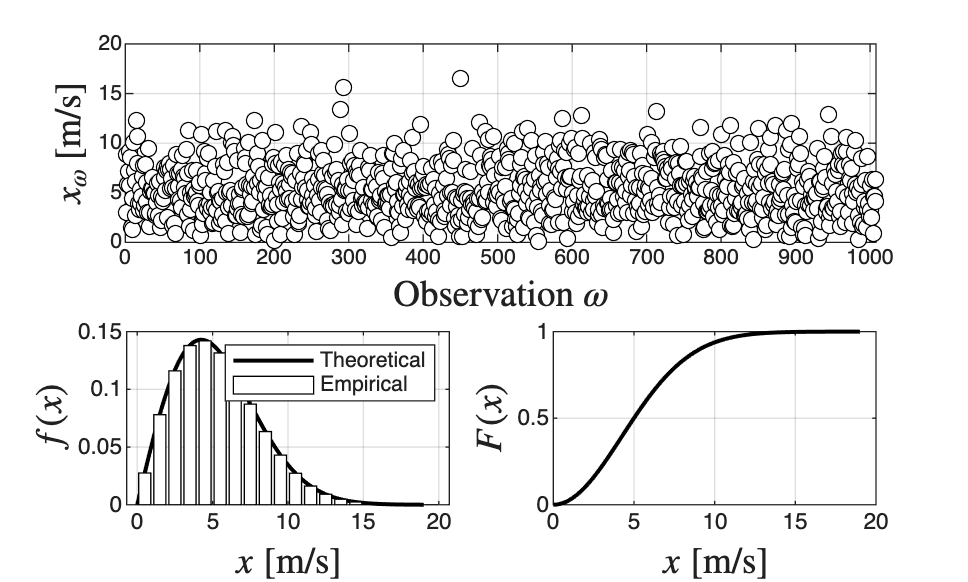

scale=6; % m/s
shape=2; % -

figure(1)
subplot(2,2,1:2)
N=24*7*6;
xo=1:1:N;
scatter(xo,wblrnd(scale,shape,N,1),'blacko','MarkerFaceColor','white','MarkerEdgeColor','black') 
axis([0,N,0,20])
xlabel('Observation $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$ [m/s]','Interpreter','latex','FontSize',14)
grid on
box on
subplot(2,2,3)
plot(xx,wblpdf(xx,scale,shape),'black','LineWidth',1.5)
hold on
bar(x,w,'EdgeColor','black','FaceColor','white','LineWidth',0.5)
xlabel('$x\; \textrm{[m/s]}$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on
lgd=legend('Theoretical','Empirical');
lgd.FontSize = 8;
subplot(2,2,4)
plot(xx,wblcdf(xx,scale,shape),'black','LineWidth',1.5)
grid on
xlabel('$x\; \textrm{[m/s]}$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
grid on
print -depsc ch2_windspeed.eps

## Mean and mode

mean

m=wblstat(scale,shape)

m = 5.3174


% mode
mo=scale*((shape-1)/shape)^(1/shape)

mo = 4.2426

## Probability of high wind speed

prob 10-20 m/s

p=wblcdf(20,scale,shape)-wblcdf(10,scale,shape)

p = 0.0622

## Note

As in the book, the wind speed is in the 10-20 m/s range only 6% of the time: the turbine rarely operates in its high-power range at this location.